# Chapter 3: Seizure Detection using EEG Signal

We will classify human EEG signals using the continuous wavelet transform (CWT) and a deep convolutional neural network (CNN). 

SqueezeNet is a deep CNN originally designed to classify images in 1000 categories. We reuse the network architecture of the CNN to classify EEG signals based on images from the CWT of the time series data. The data used in this example are publicly available from [UCI Machine Learning Repository](https://archive.ics.uci.edu/ml/index.html)

**1. Organize the Dataset into Seizure and Non-Seizure Subdirectories**

The original dataset from the reference consists of 5 different folders, each with 100 files, with each file representing a single subject/person. Each file is a recording of brain activity for 23.6 seconds. The corresponding time-series is sampled into 4097 data points. Each data point is the value of the EEG recording at a different point in time. So we have total 500 individuals with each has 4097 data points for 23.5 seconds.

We divided and shuffled every 4097 data points into 23 chunks, each chunk contains 178 data points for 1 second, and each data point is the value of the EEG recording at a different point in time. So now we have 23 x 500 = 11500 pieces of information(row), each information contains 178 data points for 1 second(column), the last column represents the label y {1,2,3,4,5}.

The response variable is y in column 179, the Explanatory variables X1, X2, …, X178

y contains the category of the 178-dimensional input vector. Specifically y in {1, 2, 3, 4, 5}:

5 - eyes open, means when they were recording the EEG signal of the brain the patient had their eyes open

4 - eyes closed, means when they were recording the EEG signal the patient had their eyes closed

3 - Yes they identify where the region of the tumor was in the brain and recording the EEG activity from the healthy brain area

2 - They recorder the EEG from the area where the tumor was located

1 - Recording of seizure activity

All subjects falling in classes 2, 3, 4, and 5 are subjects who did not have epileptic seizure. Only subjects in class 1 have epileptic seizure. Our motivation for creating this version of the data was to simplify access to the data via the creation of a .csv version of it. Although there are 5 classes we have done binary classification, namely class 1 (Epileptic seizure) against the rest.

This Dataset collect from [UCI Machine Learning Repository](https://archive.ics.uci.edu/ml/index.html)

**Objective:** Divide the dataset into two categories: **seizure** (y=1) and **non-seizure** (y=2,3,4,5). Create corresponding subdirectories to store these categorized data.

% Define the filename
filename = 'D:\Documents\IIT PATNA\SEM 7\Biomedical signal processing\ppt\Epileptic Seizure Recognition.csv\Epileptic Seizure Recognition.csv';  % Replace with your actual filename

% Detect import options
opts = detectImportOptions(filename);

% Display original variable names for verification
disp('Original Variable Names:');

Original Variable Names:


disp(opts.VariableNames);

    {'Unnamed'}    {'X1'}    {'X2'}    {'X3'}    {'X4'}    {'X5'}    {'X6'}    {'X7'}    {'X8'}    {'X9'}    {'X10'}    {'X11'}    {'X12'}    {'X13'}    {'X14'}    {'X15'}    {'X16'}    {'X17'}    {'X18'}    {'X19'}    {'X20'}    {'X21'}    {'X22'}    {'X23'}    {'X24'}    {'X25'}    {'X26'}    {'X27'}    {'X28'}    {'X29'}    {'X30'}    {'X31'}    {'X32'}    {'X33'}    {'X34'}    {'X35'}    {'X36'}    {'X37'}    {'X38'}    {'X39'}    {'X40'}    {'X41'}    {'X42'}    {'X43'}    {'X44'}    {'X45'}    {'X46'}    {'X47'}    {'X48'}    {'X49'}    {'X50'}    {'X51'}    {'X52'}    {'X53'}    {'X54'}    {'X55'}    {'X56'}    {'X57'}    {'X58'}    {'X59'}    {'X60'}    {'X61'}    {'X62'}    {'X63'}    {'X64'}    {'X65'}    {'X66'}    {'X67'}    {'X68'}    {'X69'}    {'X70'}    {'X71'}    {'X72'}    {'X73'}    {'X74'}    {'X75'}    {'X76'}    {'X77'}    {'X78'}    {'X79'}    {'X80'}    {'X81'}    {'X82'}    {'X83'}    {'X84'}    {'X85'}    {'X86'}    {'X87'}    {'X88'}    {'X89'}    {'X90'}    


% Identify and exclude the 'Unnamed (A1)' column
unnamedCol = find(contains(opts.VariableNames, 'Unnamed'));
if ~isempty(unnamedCol)
    opts.SelectedVariableNames = opts.VariableNames;
    opts.SelectedVariableNames(unnamedCol) = [];
    disp(['Excluded column: ', opts.VariableNames{unnamedCol}]);
else
    disp('No Unnamed columns found.');
end

Excluded column: Unnamed



% Read the table with adjusted options
data = readtable(filename, opts);

% Display the first few rows to verify
disp('Data Preview:');

Data Preview:


disp(head(data));

     X1      X2     X3      X4     X5     X6      X7      X8     X9     X10    X11    X12     X13     X14     X15     X16     X17      X18      X19      X20     X21     X22     X23     X24     X25    X26     X27    X28    X29    X30    X31    X32    X33    X34    X35     X36     X37     X38     X39    X40    X4

% Check if 'y' exists in the table
if ismember('y', data.Properties.VariableNames)
    % Convert 'y' to categorical if it's not already
    if ~iscategorical(data.y)
        data.y = categorical(data.y);
    end
    disp('Converted ''y'' to categorical.');
else
    error("The 'y' column was not found in the dataset.");
end

Converted 'y' to categorical.



% Verify the conversion
disp('Response Variable Classes:');

Response Variable Classes:


disp(categories(data.y));

    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}



% Define seizure and non-seizure labels
seizureLabel = '1';  % Categorical
nonSeizureLabels = {'2', '3', '4', '5'};

% Create directories to store categorized data
dataDir = 'data';
seizeDir = fullfile(dataDir, 'seize');
nonSeizeDir = fullfile(dataDir, 'non_seize');

% Create directories if they don't exist
if ~exist(seizeDir, 'dir')
    mkdir(seizeDir);
end

if ~exist(nonSeizeDir, 'dir')
    mkdir(nonSeizeDir);
end

% Separate the data
seizeData = data(data.y == seizureLabel, :);
nonSeizeData = data(ismember(data.y, categorical(nonSeizureLabels)), :);

% Display counts
disp(['Number of Seizure Samples: ', num2str(height(seizeData))]);

Number of Seizure Samples: 2300


disp(['Number of Non-Seizure Samples: ', num2str(height(nonSeizeData))]);

Number of Non-Seizure Samples: 9200


**2. Plot a Representative of Each EEG Category**

**Objective:** Visualize a sample EEG signal from each category to understand the data better.

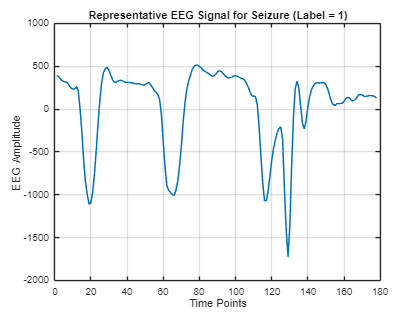

% Function to plot a representative EEG signal
function plotRepresentativeEEG(data, label, categoryName)
    % Ensure 'data' is a table with at least one row
    if istable(data) && height(data) >= 1
        % Extract the first row's numerical data (X1 to X178)
        signal = data{1, 1:178};  % Adjust indices if necessary
    else
        error('Input data must be a table with at least one row.');
    end
    
    % Plot the EEG signal
    figure;
    plot(signal, 'LineWidth', 1.5);
    title(['Representative EEG Signal for ', categoryName, ' (Label = ', char(label), ')']);
    xlabel('Time Points');
    ylabel('EEG Amplitude');
    grid on;
end

% Plot for Seizure
plotRepresentativeEEG(seizeData, seizureLabel, 'Seizure');

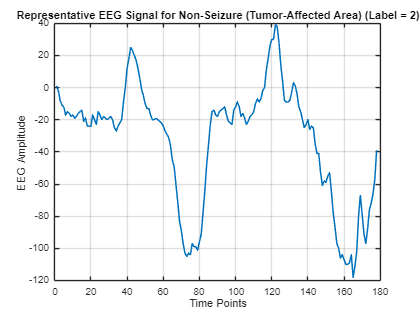

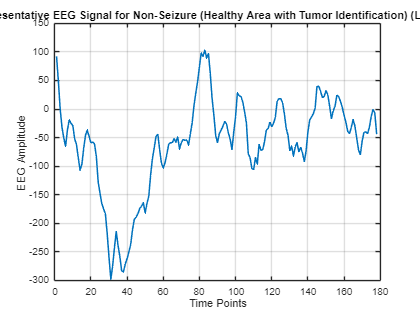

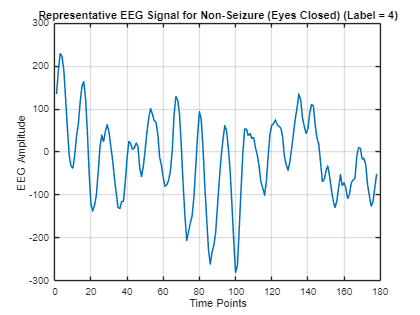

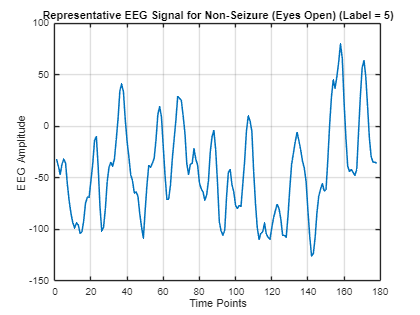


% Plot for Non-Seizure Classes
nonSeizureCategories = {'2', '3', '4', '5'};
nonSeizureNames = {'Non-Seizure (Tumor-Affected Area)', ...
                   'Non-Seizure (Healthy Area with Tumor Identification)', ...
                   'Non-Seizure (Eyes Closed)', ...
                   'Non-Seizure (Eyes Open)'};

for i = 1:length(nonSeizureCategories)
    label = nonSeizureCategories{i};
    categoryName = nonSeizureNames{i};
    sampleData = nonSeizeData(nonSeizeData.y == label, :);
    if ~isempty(sampleData)
        plotRepresentativeEEG(sampleData, label, categoryName);
    else
        warning(['No data found for label ', label]);
    end
end

**3. Create Time-Frequency Representations (Scalograms)**

**Objective:** Generate scalograms (time-frequency representations) of the EEG signals using Continuous Wavelet Transform (CWT).

A scalogram is the absolute value of the CWT coefficients of a signal. To create the scalograms, precompute a CWT filter bank. Precomputing the CWT filter bank is the preferred method when obtaining the CWT of many signals using the same parameters.

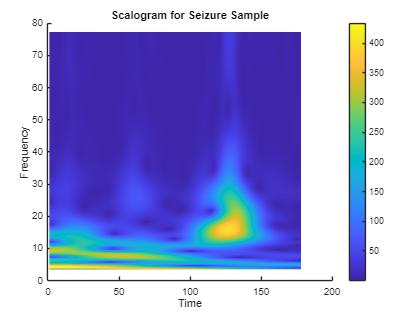

% Define parameters
samplingRate = 178; % Assuming 1 second corresponds to 178 data points

% Precompute the CWT filter bank
cwtFilter = cwtfilterbank(SignalLength = 178,...
                          SamplingFrequency = samplingRate, ...
                          VoicesPerOctave = 12);

% Example: Generate scalogram for the first seizure sample
sampleSignal = seizeData{1, 1:178};
[cfs, frequencies] = wt(cwtFilter, sampleSignal);

% Plot the scalogram
figure;
surface(1:178, frequencies, abs(cfs));
shading interp;
xlabel('Time');
ylabel('Frequency');
title('Scalogram for Seizure Sample');
colorbar;

**4. Create Scalograms as RGB Images Compatible with SqueezeNet**

**Objective:** Convert scalograms into RGB images of size 224x224x3, suitable for input into SqueezeNet.

function saveScalogramAsRGB(signal, cwtFilter, outputPath)
    
    [cfs, ~] = wt(cwtFilter, signal);
    scalogram = abs(cfs);
    
    % Normalize the scalogram
    scalogramNorm = mat2gray(scalogram);
    
    % Resize to 224x224
    scalogramResized = imresize(scalogramNorm, [224 224]);
    
    % Convert to RGB by replicating the grayscale image across 3 channels
    rgbScalogram = repmat(scalogramResized, [1, 1, 3]);
    
    % Save the image
    imwrite(rgbScalogram, outputPath);

end

% Generate and save scalograms for all seizure samples
for i = 1:height(seizeData)
    signal = seizeData{i, 1:178};
    filename = sprintf('seize_%05d.png', i);
    outputPath = fullfile(seizeDir, filename);
    saveScalogramAsRGB(signal, cwtFilter, outputPath);
end

% Similarly, generate and save scalograms for non-seizure samples
for i = 1:height(nonSeizeData)
    signal = nonSeizeData{i, 1:178};
    filename = sprintf('non_seize_%05d.png', i);
    outputPath = fullfile(nonSeizeDir, filename);
    saveScalogramAsRGB(signal, cwtFilter, outputPath);
end

disp('Scalogram images saved as RGB images in respective directories.');

Scalogram images saved as RGB images in respective directories.


**5. Load Scalogram Images as an Image Datastore**

**Objective:** Utilize MATLAB's `imageDatastore` to manage and preprocess the image data for training.

% Define the image datastore
imds = imageDatastore(dataDir, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Display the count of each category
labelCount = countEachLabel(imds);
disp(labelCount);

      Label      Count
    _________    _____

    non_seize    9200 
    seize        2300 




% Split the data into training and validation sets (80%-20%)
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomize');

% Display the number of images in each set
disp(['Number of training images: ', num2str(numel(imdsTrain.Files))]);

Number of training images: 9200


disp(['Number of validation images: ', num2str(numel(imdsValidation.Files))]);

Number of validation images: 2300


**6. Load and Modify SqueezeNet**

**Objective:** Load the pre-trained SqueezeNet model and modify its final layers to suit your classification task.

% Load pre-trained SqueezeNet
netsqz = imagePretrainedNetwork("squeezenet");

% Display number of layers
disp("Number of Layers: "+num2str(numel(netsqz.Layers)))

Number of Layers: 68



% Display the first layer
netsqz.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]



% Inspect the last five layers
disp('Last five layers before modification:');

Last five layers before modification:


netsqz.Layers(end-4:end)

ans =   5×1 Layer array with layers:

     1   'conv10'         2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     2   'relu_conv10'    ReLU                         ReLU
     3   'pool10'         2-D Global Average Pooling   2-D global average pooling
     4   'prob'           Softmax                      softmax
     5   'prob_flatten'   Flatten                      Flatten


% Replace the last dropout layer with a dropout layer of probability 0.6
% Assuming the last dropout layer is the second to last layer
tmpLayer = netsqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,"Name","new_dropout");
netsqz = replaceLayer(netsqz,tmpLayer.Name,newDropoutLayer);

% Determine the number of classes
numClasses = numel(categories(imdsTrain.Labels));

% Replace the final convolutional layer to match the number of classes
tmpLayer = netsqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        "Name","new_conv", ...
        "WeightLearnRateFactor",10, ...
        "BiasLearnRateFactor",10);
netsqz = replaceLayer(netsqz,tmpLayer.Name,newLearnableLayer);

netsqz.Layers(end-4:end)

ans =   5×1 Layer array with layers:

     1   'new_conv'       2-D Convolution              2 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     2   'relu_conv10'    ReLU                         ReLU
     3   'pool10'         2-D Global Average Pooling   2-D global average pooling
     4   'prob'           Softmax                      softmax
     5   'prob_flatten'   Flatten                      Flatten


augimgsTrain = augmentedImageDatastore([227 227],imdsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imdsValidation);


**8. Set Training Options and Train SqueezeNet**

**Objective:** Define training parameters and train the modified SqueezeNet model on your dataset.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:01:02       0.0003                           0.80107                                    40.217
            1        1       00:01:02       0.0003         0.86754                                    44                      
           23        1       00:03:15       0.0003         0.26638           0.27024                  88                87.696
           46        1       00:05:25       0.0003          0.2359           0.13163                  86                94.913
           50        1       00:05:42       0.0003        0.032084                                   100                      
           69        1       00:07:49       0.0003         0.10432            0.1586                  98       

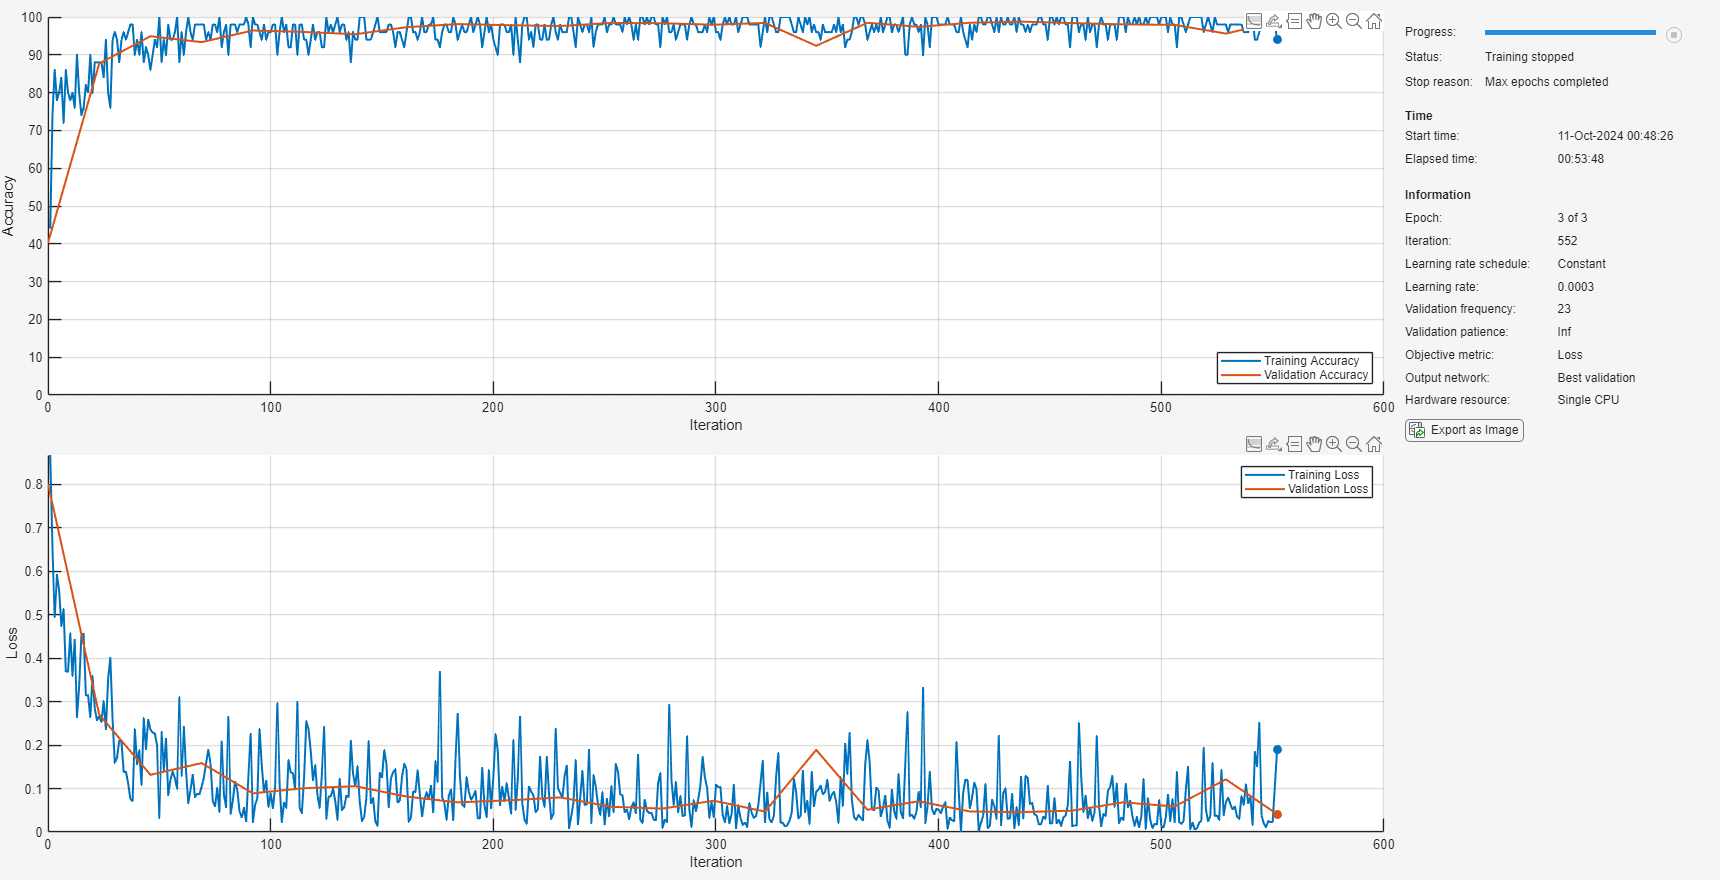

ilr = 3e-4;
miniBatchSize = 50;
maxEpochs = 3;
valFreq = ((floor(numel(augimgsTrain.Files)/miniBatchSize))/8);
opts = trainingOptions("sgdm", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=maxEpochs, ...
    InitialLearnRate=ilr, ...
    ValidationData=augimgsValidation, ...
    ValidationFrequency=valFreq, ...
    Verbose=1, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    ExecutionEnvironment = "cpu");

trainedSN = trainnet(augimgsTrain,netsqz,"crossentropy",opts);

**9. Evaluate SqueezeNet Accuracy**

Evaluate the network using the validation data.

% Predict labels for validation data
classNames = unique(imdsTrain.Labels);
YPred = scores2label(scores,classNames);
% Get the true labels
YTrue = imdsValidation.Labels;

% Calculate accuracy
accuracy = mean(YPred == YTrue);
disp(['SqueezeNet Accuracy on Validation Data: ', num2str(100 * accuracy), '%']);

SqueezeNet Accuracy on Validation Data: 98.7826%


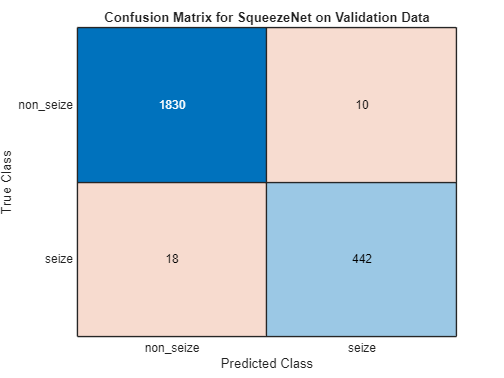

% Display confusion matrix
figure;
confusionchart(YTrue, YPred);
title('Confusion Matrix for SqueezeNet on Validation Data');


% Calculate additional metrics (e.g., precision, recall)
C = confusionmat(YTrue, YPred);
precision = diag(C) ./ sum(C, 1)';
recall = diag(C) ./ sum(C, 2);
F1 = 2 * (precision .* recall) ./ (precision + recall);

% Display metrics
disp('Precision for each class:');

Precision for each class:


disp(precision);

    0.9903
    0.9779



disp('Recall for each class:');

Recall for each class:


disp(recall);

    0.9946
    0.9609



disp('F1 Score for each class:');

F1 Score for each class:


disp(F1);

    0.9924
    0.9693



# Conclusion

We demonstrated the effectiveness of wavelet transforms, particularly the continuous wavelet transform (CWT), in extracting meaningful features from EEG signals for seizure detection. Wavelets are particularly useful in signal processing due to their ability to capture both time and frequency information, making them well-suited for analyzing non-stationary signals like EEG data. This dual capability allows for a more comprehensive understanding of the signal's behavior, facilitating better classification outcomes.

Utilizing transfer learning with the SqueezeNet convolutional neural network, we achieved an impressive classification accuracy of **98.7826%** in detecting seizures from EEG signals. This high level of accuracy showcases the potential of deep learning approaches in enhancing the diagnosis and monitoring of epileptic activity. Overall, our findings highlight the synergy between wavelet transforms and CNN architectures in efficiently processing and classifying EEG data, paving the way for advanced applications in neurological health monitoring.

# References:

- Polikar, R. (n.d.). *The wavelet tutorial*. Rowan University. [https://users.rowan.edu/~polikar/WTtutorial.html](https://users.rowan.edu/~polikar/WTtutorial.html)

- Jain, A. K. (2018). *Textbook of physiology* (6th ed.). Avichal Publishing Company.

- Harrison, T. R., Fauci, A. S., Kasper, D. L., et al. (2015). *Harrison's principles of internal medicine* (20th ed.). McGraw-Hill Education.

- MathWorks. (n.d.). *Classify time series using wavelet analysis and deep learning*. [https://in.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html](https://in.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html)